# Counting the Number of coins in an image

## Image procssing

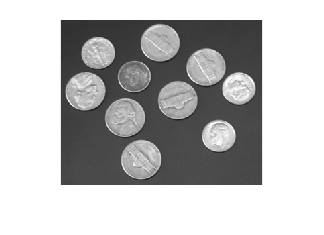

img=imread('coins.png');
imshow(img)

## Edge detection

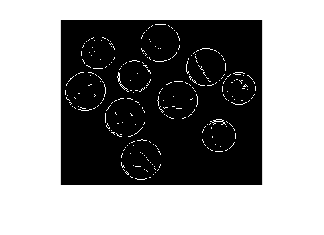

im_boundary=edge(img);
imshow(im_boundary)

## Filling gaps in the edges

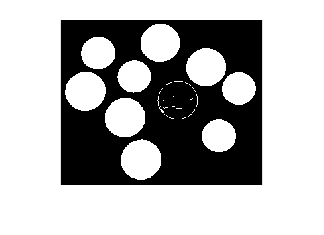

filled_img=imfill(im_boundary,'holes');
imshow(filled_img)

## Removing all noise

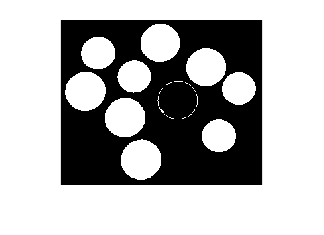

cleaned_img=bwareaopen(filled_img,100);
imshow(cleaned_img)

## Labelling and counting of coins

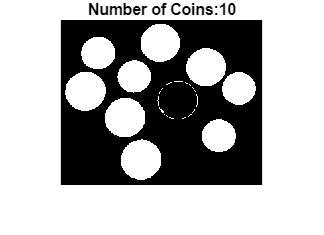

[L,num]=bwlabel(cleaned_img);
imshow(L);
title(['Number of Coins:',num2str(num)]);

disp(['Number of coins detected:',num2str(num)]);

Number of coins detected:10


## Coins in RGB

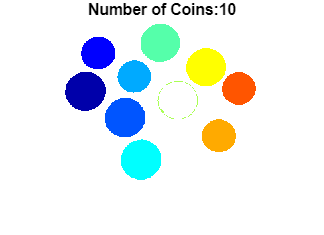

[L,num]=bwlabel(cleaned_img);
imshow(label2rgb(L));
title(['Number of Coins:',num2str(num)]);

disp(['Number of coins detected:',num2str(num)]);

Number of coins detected:10
